# **CS/SE 4X03 Tutorial - Week 5 - Interpolation**

## Exercise 1 - 4.1.1

**Problem: **Use the Lagrange interpolation process to obtain a polynomial of least degree that assumes these values:


$$\begin{array}{ll}
x \;\\ \hline
y\;
\end{array}
\left|
\begin{array}{cccc}
\;0 & 2 & 3 & 4\\ \hline
\;7 &11 & 28 & 63
\end{array}$$


**Answer: To solve this problem: find the cardinal polynomials and plug into the interpolation formula:**

We have:


$$p_n(x) = \sum_{i=0}^n \ell_i(x) f(x_i)$$


with


$$\ell_i(x) = \prod_{j=0,j\neq i}^n \frac{x-x_j}{x_i-x_j}$$


Now compute $\ell_i$


$$\begin{array}{ll}
\ell_0(x) = \frac{(x-2)(x-3)(x-4)}{(0-2)(0-3)(0-4)} & = \frac{(x-2)(x-3)(x-4)}{24} \\
\ell_1(x) = \frac{(x-0)(x-3)(x-4)}{(2-0)(2-3)(2-4)} 
& = \frac{x(x-3)(x-4)}{4} \\ 
\ell_2(x) = \frac{(x-0)(x-2)(x-4)}{(3-0)(3-2)(3-4)} & = \frac{x(x-2)(x-4)}{3} \\
\ell_3(x) = \frac{(x-0)(x-2)(x-3)}{(4-0)(4-2)(4-3)} & = \frac{x(x-2)(x-3)}{8}
\end{array}$$


Plug into our $p_n(x)$ with $f(x_i)=y_i$


$$\begin{array}{ll}
p_3(x)=&-\frac{7}{24}(x-2)(x-3)(x-4) + \frac{11}{4}x(x-3)(x-4)\\ 
&-\frac{28}{3}x(x-2)(x-4)+ \frac{63}{8}x(x-2)(x-3)\\
p_3(x) = &7 - 2x + x^3
\end{array}$$


We can check our result using MATLAB

clear;

% X and Y data
Y = [7; 11; 28; 63];
X = [0; 2; 3; 4];

% X data as needed for cardinal polynomial
%   This is X, changed so that the (n+1)th entry is last. 
X0 = [X(2:4); X(1)];
X1 = [X(1); X(3:4); X(2)];
X2 = [X(1:2); X(4); X(3)];
X3 = X;

% nth Cardinal polynomial, where xi has (n+1)th entry last.
l = @(t,xi)(t-xi(1))*(t-xi(2))*(t-xi(3))/((xi(4)-xi(1))*(xi(4)-xi(2))*(xi(4)-xi(3)));

% i = 0:3 cardinal polynomials
l0 = @(t)(l(t,X0));
l1 = @(t)(l(t,X1));
l2 = @(t)(l(t,X2));
l3 = @(t)(l(t,X3));

% For the sake of checking our answer:
syms x;
% We will cast this as an array to vectorize the problem; removing a for
% loop
ell = @(t)[l0(t); l1(t); l2(t); l3(t)];
% Note: The following computes an inner product
p(x) = Y'*ell(x)

$$p(x) = \frac{63\,x\,\left(x-2\right)\,\left(x-3\right)}{8}-\frac{28\,x\,\left(x-2\right)\,\left(x-4\right)}{3}+\frac{11\,x\,\left(x-3\right)\,\left(x-4\right)}{4}-\frac{7\,\left(x-2\right)\,\left(x-3\right)\,\left(x-4\right)}{24}$$

This is the long form of the polynomial we derived above. MATLAB includes the `simplify` function which we can use to reduce this:

simplify(p) % This simplifies our symbolic expression

$$ans(x) = x^{3}-2\,x+7$$

Let's plot our solution against the data now

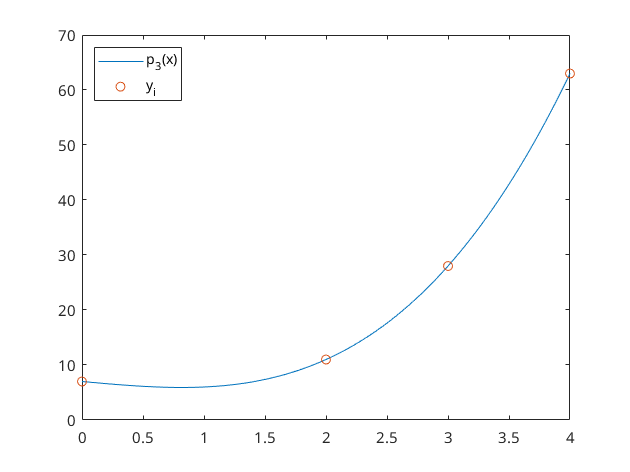

clf;
t = linspace(X(1),X(end));
plot(t,p(t),X,Y,'o');
legend('p_3(x)','y_i',"Location","northwest")

## Exercise 2 - 4.2.1

**Problem: **Use a divided-difference table to show that the following data can be represented by a polynomial of degree 3:


$$\begin{array}{ll}
x \;\\ \hline
y\;
\end{array}
\left|
\begin{array}{cccc}
\;-2 & -1 & 0 & 1 & 2 & 3\\ \hline
\;1  & 4 & 11 & 16 & 13 & -4
\end{array}
$$


What is the Newton interpolating polynomial?

**Answer:** We need to compute up to the third differences to check this result.

**First differences:**

**Recall: ** $FD_i = \frac{y_{i+1} - y_i}{x_{i+1}-x_i}$

Ex:


$$FD_0 = \frac{y_1 - y_0}{x_1 -x_0} = \frac{4 - 1}{-1 - (-2)}= 3$$



$$\begin{array}{rr}
x_i & y_i  \;\\ \hline 
-2 & 1 \;\\ 
-1 & 4 \;\\
0 & 11 \;\\
1 & 16 \;\\
2 & 13 \;\\
3 & -4  \;
\end{array}
\left|
\begin{array}{l}
\\
\\
\\
\\
\\
\\
\\
\\
\end{array}
\begin{array}{r}
\;FD_i\\\hline
\; 3\\
\; 7\\
\; 5\\
\; -3\\
\; -17\\
\\
\\
\end{array}$$


Blank means no entry

**Second Differences:**

**Recall: **$SD_i = \frac{FD_{i+1}-FD_{i}}{x_{i+2}-x_i}$

Ex:


$$SD_0 = \frac{FD_1 - FD_0}{x_2 -x_0} = \frac{7 - 3}{0 - (-2)}= 2$$



$$\begin{array}{rr}
x_i & y_i  \;\\ \hline 
-2 & 1 \;\\ 
-1 & 4 \;\\
0 & 11 \;\\
1 & 16 \;\\
2 & 13 \;\\
3 & -4  \;
\end{array}
\left|
\begin{array}{l}
\\
\\
\\
\\
\\
\\
\\
\\
\end{array}
\begin{array}{rr}
\;FD_i & SD_i\\\hline
\; 3 & 2\\
\; 7 & -1\\
\; 5 & -4\\
\; -3 & -7\\
\; -17\\
\\
\\
\end{array}$$


**Third Differences: **

**Recall: **$TD_i = \frac{SD_{i+1}-SD_{i}}{x_{i+3}-x_i}$

Ex:


$$TD_0 = \frac{SD_1 - SD_0}{x_3 -x_0} = \frac{-1 - 2}{1 - (-2)}  = -1$$



$$\begin{array}{rr}
x_i & y_i  \;\\ \hline 
-2 & 1 \;\\ 
-1 & 4 \;\\
0 & 11 \;\\
1 & 16 \;\\
2 & 13 \;\\
3 & -4  \;
\end{array}
\left|
\begin{array}{l}
\\
\\
\\
\\
\\
\\
\\
\\
\end{array}
\begin{array}{rrr}
\;FD_i & SD_i & TD_i\\\hline
\; 3 & 2 & -1\\
\; 7 & -1 & -1\\
\; 5 & -4 & -1\\
\; -3 & -7\\
\; -17\\
\\
\\
\end{array}$$


**Fourth Differences:**

Since all of our third differences have the same value, our fourth (and higher) differences will be zero.

**Recall:**

Newton interpolating formula:


$$p_n(x) = \sum_{i=0}^na_i\prod_{j=0}^{i-1}(x-x_j)$$



$$\Rightarrow p_3(x)= a_0+a_1(x-x_0) +a_2(x-x_0)(x-x_1)+
a_3(x-x_0)(x-x_1)(x-x_2)$$


Plugging in $a_i$ from the first row of our divided differences table:


$$\begin{array}{ll}
p_3(x)&= a_0+a_1(x-x_0) +a_2(x-x_0)(x-x_1)+
a_3(x-x_0)(x-x_1)(x-x_2)\\
p_3(x) &= 1 + 3(x-(-2))+2(x-(-2))(x-(-1))-1(x-(-2))(x-(-1))(x-0)\\
p_3 (x) &= 11+7x-x^2-x^3
\end{array}$$


clear;
syms x;
p0 = 1;
p1(x) = 3*(x+2);
p2(x) = 2*(x+2)*(x+1);
p3(x) = -1*(x+2)*(x+1)*x;

p = p0+p1+p2+p3

$$p(x) = 3\,x+\left(2\,x+4\right)\,\left(x+1\right)-x\,\left(x+1\right)\,\left(x+2\right)+7$$

simplify(p)

$$ans(x) = -x^{3}-x^{2}+7\,x+11$$

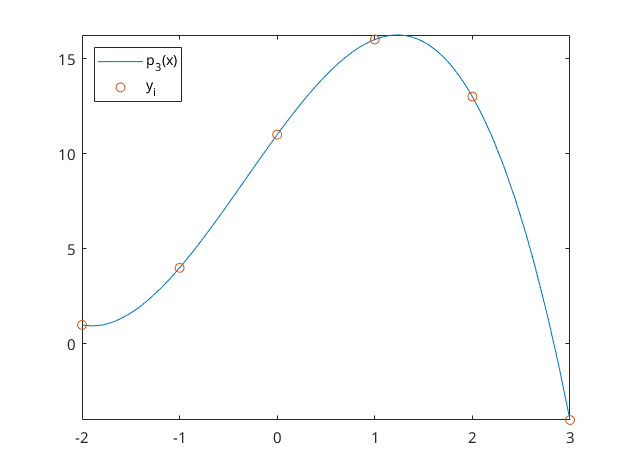

clf;
p(x) = 1 + 3*(x+2)+2*(x+2)*(x+1)-(x+2)*(x+1)*x;
fplot(p)
xlim([-2 3]);
hold on;
x0 = [-2 -1 0 1 2 3];
y0 = [1 4 11 16 13 -4];
plot(x0,y0,'o')
legend('p_3(x)','y_i',"Location",'northwest')
hold off;

## Exercise 3 - 4.2.5(a)

### Theorem 1

If $p$ is the polynomial of degree at most $n$ that interpolates $f$ at the $n+1$ distinct nodes $x_0,x_1,...,x_n$ belonging to an interval $[a,b]$ and if $f^{(n+1)}$ is continuous, then for each $x$ in $[a,b]$, there is a $\xi$ in $(a,b)$ for which:


$$f(x) - p(x) = \frac{1}{(n+1)!}f^{(n+1)}(\xi)\prod_{i=0}^n(x-x_i)$$


### Theorem 2

Let $f$ be a function such that $f^{(n+1)}$ is continuous on $[a,b]$ and satisfied $\left|f^{(n+1)}(x)\right| \leq M$. Let $p$ be the polynomial of degree $\leq n$ that interpolates $f$ at $n+1$ **equally spaced nodes** in $[a,b]$, including the endpoints. Then on $[a,b]$,


$$\left|f(x)-p(x)\right| \leq \frac{1}{4(n+1)}Mh^{n+1}$$


**Problem: **Using Theorem 1, show directly that the maximum interpolation error is bounded by the following expression and compare it to the bounds given by Theorem 2:

$\frac{h^2M}{8}$ for the linear interpolation,

 where $h = x_1 - x_0$ and $M=\max_{x\in[x_0, x_1]}\left| f''(x)\right|$

**Answer: **We will take Theorem 1 for the linear case and compare it to bounds of Theorem 2.

**Note**: 


$$\varepsilon(x) = f(x) - p(x) = \frac{f''(\xi)}{2}(x-x_0)(x-x_1) = \frac{f''(\xi)}{2}(x^2-(x_0+x_1)x + x_0x_1)$$


We can obtain the maximum by extremizing this with respect to x:


$$\frac{d}{dx}\varepsilon(x)=\frac{f''(\xi)}{2}(2x-(x_0+x_1))=0$$



$$\Rightarrow x = \frac{x_0+x_1}{2}$$


Substituting into $\varepsilon(x)$:


$$\begin{array}{ll}
\varepsilon(x) &= \frac{f''(\xi)}{2}
\left(\frac{(x_0+x_1)^2}{4}-\frac{(x_0+x_1)^2}{2} + x_0x_1\right)\\
&= -\frac{f''(\xi)}{2}\cdot\frac{(x_1-x_0)^2}{4}
\end{array}$$


We can rewrite using $h=x_1-x_0$:


$$\begin{array}{rl}
|\varepsilon(x)| &= \frac{f''(\xi)h^2}{8}\\
\Rightarrow \max_{x_0\leq t\leq x_1}|\varepsilon(t)| & = \frac{Mh^2}{8}
\end{array}$$


Now compare this error to the bounds of Theorem 2 in the linear case as well.


$$\begin{array}{ll}
\left|f(x) - p(x)\right| &\leq \frac{1}{4(1+1)}Mh^{1+1}\\
\left| f(x) - p(x)\right| &\leq \frac{1}{8}Mh^2
\end{array}$$


This confirms what we just derived directly.

## Exercise 4 - 4.2.7

**Problem: **Given the data:


$$\matrix{x & \sin(x) & \cos(x) \cr
\hline 0.70 & 0.6442176872 & 0.7648421873 \cr
0.71 & 0.6518337710 & 0.7583618760}$$


find approximate values of $\sin 0.705$ and $\cos 0.702$ by linear interpolation. What is the error?

**Answer: **

**Recall:** Linear interpolation $y=b+mx$:


$$p(x) = y_0 + \left(\frac{y_1-y_0}{x_1-x_0}\right)\left(x-x_0\right)$$


For sin:

We have our $x_i$ and $y_i$ values given to us, we need to solve using the given $x=0.705$


$$\begin{array}{ll}
p(0.705)& = 0.6442176872 + \left(\frac{0.6518337710-0.6442176872}{0.71-0.70}\right)\left(0.705-0.70\right)\\
p(0.705) &= 0.6480257291
\end{array}$$


clear;
% row 1 = x; row 2 = y
p = @(x,data)(data(2,1) + (data(2,2) - data(2,1))/(data(1,2) - data(1,1))*(x - data(1,1)));

sin_data = [0.70 0.71
            0.6442176872 0.6518337710];

% We want to solve 0.705
x = 0.705;

% Now compare to the known value for the error
error = sin(0.705) - p(x,sin_data);
p(x,sin_data), error

Now for $\cos(0.702)$:

cos_data = [0.70 0.71
            0.7648421873 0.7583618760];

% We want to solve x = 0.702;
x = 0.702;

% Now compare to the known value for the error
error = cos(0.702)-p(x,cos_data);
p(x,cos_data),error

% The error bound for the interpolation is 
h = 0.01; M = 1;
e_bound = 1/8*h^2

## Exercise 5 - 4.2.10

**Problem: **Let the function $f(x) = \ln x$ be approximated by an interpolation polynomial of degree 9 with ten **nodes uniformly distributed** in the interval $[1, 2]$. What bound can be placed on the error?

**Recall Theorem 2:**


$$\begin{array}{rl}
\left|f(x)-p(x)\right| &\leq \frac{1}{4(n+1)}Mh^{n+1}, \\
M &= \max_{x_0 \leq x \leq x_1}|f^{(n+1)}(x)|
\end{array}$$


**Answer:**

To specify $M$, we need to find the (n+1)th derivation of function $f(x) = \ln x$, which is:


$$\frac{d^{n+1}\ln x}{dx^{n+1}} =
f^{(n+1)}(x) =
 (-1)^{n}\frac{n!}{x^{n+1}}$$


So for degree $n=9$, $f^{(n+1)}(x) $ is $ f^{(10)}$:

                                                                                                                                          
$$\begin{array}{rl}

M &= \max_{x_0 \leq x \leq x_1}|f^{(10)}(x)|
\end{array}$$


we need to find the maximum $ f^{(10)}(x)$ in the interval [1, 2], as shown above $ |f^{(10)}(x)|$ is:

                                                                                                                                                
$$|f^{(10)}(x)| =
 \frac{9!}{x^{10}}$$


we know that for $x > 1$, $|f^{(10)}(x)| $ is monotone decreasing, the larges value occurs when $x = 1$, which is can be indicated by matlab code below:

$\left|f^{(10)}(x)\right| \leq 9!$ for $x\in[1,2]$

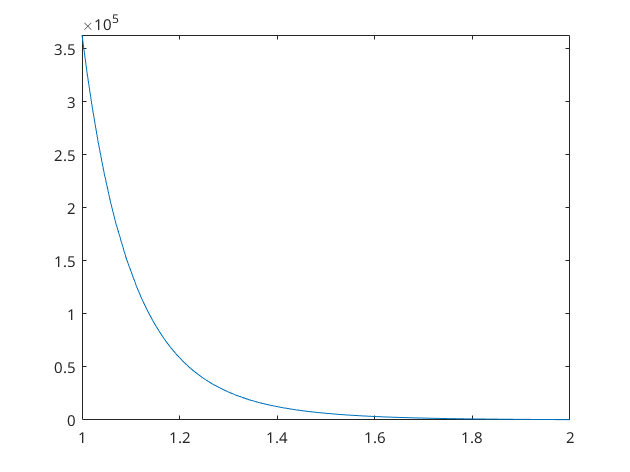

clf;
syms x;
fplot(abs(diff(log(x),10)))
xlim([1,2]);

Using 


$$\begin{array}{ll}
M&=\max_{1\leq x \leq 2}\left| f^{(n+1)}(1)\right| =\frac{9!}{(1)^{10}}= 9! \\
h&=\frac{2-1}{9}=\frac{1}{9} 
\end{array}$$


Now, with Theorem 2:

    
$$\left|f(x)-p(x)\right| \leq \frac{9!}{40}\left(\frac{1}{9}\right)^{10}\approx 2.6\times 10^{-6}$$


## Exercise 6 - 4.2.13

**Problem: **Suppose $\cos x$ is to be approximated by an interpolating polynomial of degree $n$, using $n + 1$ **equally spaced nodes** in the interval $[0, 1]$. 

**a)** How accurate is the approximation? (Express your answer in terms of $n$).

**b)** How accurate is the approximation when $n=9$?

**c) **For what values of $n$ is the error less than $10^{-7}$?

**Answer:**

**a) **When $x\in [0,1]$:


$$f(x) = \cos(x) \rightarrow \left|f^{(n+1)}\right| \leq 1$$


Once again using Theorem 2:

$ |\varepsilon| \leq \frac{Mh^{n+1}}{4(n+1)}
$ where M is the bound $|f^n(x)|$

And since $f(x)=cos(x)$ we know the derivatives are all bounded $|f^n(x)|\leq1$

And since we are using uniformly distributed nodes in [0,1] : $h = \frac{1-0}{n} = \frac{1}{n}$:


$$\left| \varepsilon \right| \leq \frac{1}{4(n+1)}\left(\frac{1}{n}\right)^{n+1}$$


**b)**


$$n=9 \rightarrow\frac{1}{4\times10}\left( \frac{1}{9}\right)^{10}\approx 7.2\times10^{-12}$$


**c) **Using trial and error, we find that when $n\ge7$:


$$\begin{array}{ll}
\left| \varepsilon \right| &\leq \frac{1}{4(8)}\left(\frac{1}{7}\right)^{8}\approx5.4\times 10^{-9}\\
& \leq 10^{-7}
\end{array}$$


Try $n = 6$: 


$$\left|\varepsilon\right|\approx1.3\times10^{-7}\gt10^{-7}$$


So at $n=7$ the error is less than $10^{-7}$:

clear all; close all
n = 6;
%n = 7;
a = 0; b = 1;
x = linspace(a,b,n+1);
y = cos(x);
p = polyfit(x,y, n);
xx = linspace(a,b,1000);
error = abs(cos(xx)- polyval(p,xx));
h  = (b-a)/n;
error_bound =  1/(4*(n+1))*h^(n+1)

error_bound = 1.2758e-07

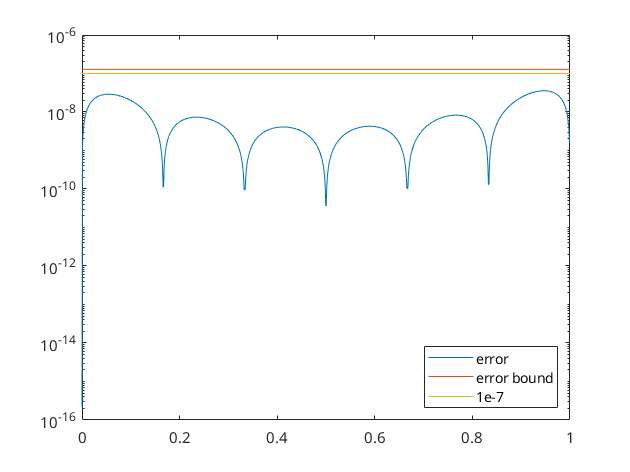

ons = ones(length(xx),1);

semilogy(xx, error, xx,error_bound*ons, xx, 1e-7*ons)
legend('error', 'error bound', '1e-7',"Location","southeast")

We can see that when $n=6$ our error bound is greater than $10^{-7}$. Despite the error being below this threshold the entire time.

Hence $n=7$ is the correct answer here, despite the error technically being in bound for $n=6$.